# MAE 144 Homework 1

David Lim

A16398479

10/11/23

## Problem 1

Link to GitHub Page:

[https://github.com/davidlim4318](https://github.com/davidlim4318)

## Problem 2

#### 2a

hw1_prob2a

x =   RR_poly with properties:
poly:    -0.6710   -2.2869   10.1755   24.1641
roots:   -5.0009   -2.0030    3.5955
   n: 3

y =   RR_poly with properties:
poly:     0.6710    2.2869  -21.5818  -62.0409   42.6886   81.5318
roots:   -6.0000   -3.0000   -1.0000    1.2681    5.3235
   n: 5

residual = 1.1369e-13

#### 2b

The controller D(s) is improper. The order of the denominator x(s) is less than the order of the numerator y(s).

hw1_prob2b

k = 5

x =   RR_poly with properties:
poly:    1.0e+08 *
    0.0000    0.0000   -0.0491   -0.1903    0.5827    1.5346
roots:   1.0e+03 *
   -2.2745   -0.0050   -0.0020    0.0031    2.1584
   n: 5

y =   RR_poly with properties:
poly:    1.0e+08 *
    0.0492    0.1921   -1.3847   -4.3786    2.2250    5.0759
roots:   -6.0000   -3.0000   -1.0000    1.1646    4.9263
   n: 5

f =   RR_poly with properties:
poly:    1.0e+09 *
    0.0000    0.0000    0.0000    0.0002    0.0031    0.0339    0.2377    1.0446    2.7935    4.2883    3.3696    1.0368
roots: -20.0302 - 0.0219i -20.0302 + 0.0219i -19.9885 - 0.0354i -19.9885 + 0.0354i -19.9628 + 0.0000i  -6.0000 - 0.0000i  -6.0000 + 0.0000i  -3.0000 - 0.0000i  -3.0000 + 0.0000i  -1.0000 - 0.0000i  -1.0000 + 0.0000i
   n: 11

residual = 1.0832e-05

If my code is correct, k needs to be = 5 in order for the controller D(s) to be proper (i.e. semi-causal, relying only on present and past inputs). This might be sufficient for a controller operating in continuous time (i.e. an analog controller). Increasing k further should eventually make D(s) strictly proper (i.e. strictly causal, only relying on past inputs).

## Problem 3

Symbolic:

syms s z1 p1
as = [1 p1 0]; 
bs = [1 z1]; 
Ds = RR_tf(bs,as); 
h = 1; 
Gz = DHL_C2D_matched(Ds,h)

Gz =   RR_tf with properties:
num:[(abs(z1)*abs(exp(-p1) - 1))/(abs(p1)*abs(exp(-z1) - 1)), -(exp(-z1)*abs(z1)*abs(exp(-p1) - 1))/(abs(p1)*abs(exp(-z1) - 1))]
den:[1, - exp(-p1) - 1, exp(-p1)]
Discrete-time transfer function with h=     1
  m=1, n=2, n_r=n-m=1, strictly proper, K=(abs(z1)*abs(exp(-p1) - 1))/(abs(p1)*abs(exp(-z1) - 1))
  z:exp(-z1)
  p:[1, exp(-p1)]

By hand:

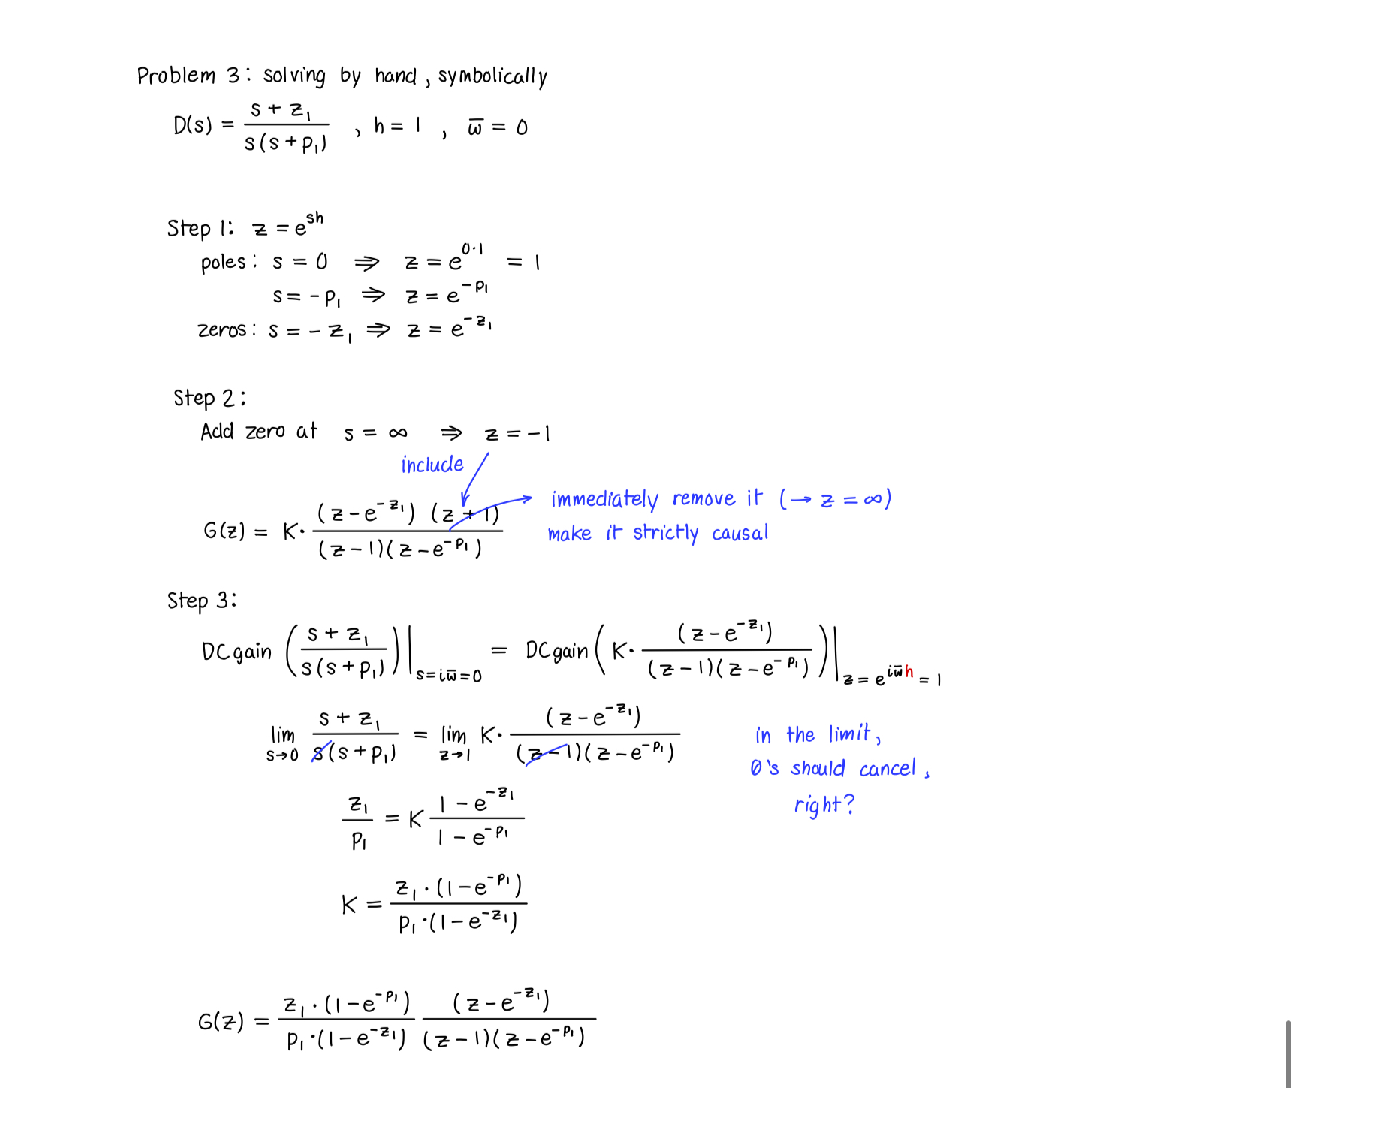

I = imread('hw1_prob3_byhand.jpeg');
imshow(I);

Numerical:

z1 = 1;
p1 = 10;
as = [1 p1 0]; 
bs = [1 z1]; 
Ds = RR_tf(bs,as); 
h = 1; 
Gz = DHL_C2D_matched(Ds,h)

Gz =   RR_tf with properties:
num:    0.1582   -0.0582
den:    1.0000   -1.0000    0.0000
Discrete-time transfer function with h=     1
  m=1, n=2, n_r=n-m=1, strictly proper, K=    0.1582
  z:    0.3679
  p:    0.0000    1.0000

Built-in function:

Ds = tf(bs,as);
Gz = zpk(c2d(Ds,h,'matched'))

Gz =
 
  0.15819 (z-0.3679)
  ------------------
  (z-1) (z-4.54e-05)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


The result D(z) generated using my function has nearly the same poles, zeros, and gain as the result generated using MATLAB's built-in function. My code is better because it works with symbolic variables and can give a symbolic result, which is pretty cool.

(My code can also handle omega_bar = 0 by effectively taking the limit and canceling out the probelmatic poles in the calculation of the gain, arriving to the result as MATLAB.)